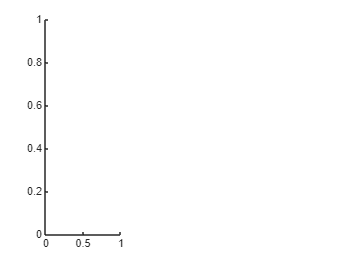

%parameters
%dSdt
beta1=0.01;
Ks=0.52;
ds=0.1;
gamma1=1;
%Dhdt
beta2=0.01;
Kh=0.62;
dh=0.3;
gamma2=1;
glc=[2,0.1,0.02];

subplot(1, 3, 1);

%when total glucose level = 2%
[St,Ht]=piecewise_glucose(glc(1));
%nuclines1
S1=0:0.01:1.7;
H1=(beta1+(S1.^3)./(Ks^3+S1.^3)).*(St-S1)./(gamma1.*S1)-ds/gamma1;

fig = figure('Position', [100, 100, 1200, 700]);clf;
subplot_width = 0.29;
subplot_height = 0.5;
subplot_gap = 0.04;
left_margin = 0.05;
bottom_margin = 0.15;

ax1 = subplot(1, 3, 1);
ax1.Position = [left_margin bottom_margin subplot_width subplot_height];
h_1=plot(S1,H1,'Color', [0.996, 0.627, 0.831],'LineWidth', 2, 'DisplayName','Sir2 nullcline');
hold on;
H2=0:0.01:1.7;
S2=(beta2+(H2.^3)./(Kh^3+H2.^3)).*(Ht-H2)./(gamma2.*H2)-dh/gamma2;
h_2=plot(S2,H2,'Color', [0.0, 0.0, 0.8], 'LineWidth', 2, 'DisplayName','HAP nullcline');
title('Glucose cencentration = 2%')
xlim([-0.1 1.8]);
ylim([-0.1 1.8]);
xlabel('Sir2');
ylabel('HAP');

%vector field
[S,H] = meshgrid(0:.1:2);
Xq = (beta1+(S.^3)./(Ks^3+S.^3)).*(St-S)-(ds+gamma1.*H).*S;
Yq = (beta2+(H.^3)./(Kh^3+H.^3)).*(Ht-H)-(ds+gamma2.*S).*H;
quiver(S,H, Xq, Yq, 'Color', [0.8, 0.9, 0.95], 'LineWidth', 1.2, 'AutoScaleFactor', 0.8, 'DisplayName','vector field');
hold on;


%Find the equilibria
%point1 [0.01,1.42]
[x_eq1, J1] = newton_gly(@gly_ode,[0.011,1.409]',[St,Ht],glc(1));
disp('Equilibrium point 1:');

Equilibrium point 1:


disp(x_eq1);

    0.0104
    1.4094



disp('Jacobian matrix 1:');

Jacobian matrix 1:


disp(J1);

   -1.5158   -0.0104
   -1.4094   -1.1697



residual = gly_ode(0,x_eq1,glc(1));
disp('residual norm 1:');

residual norm 1:


disp(norm(residual));

   3.9523e-07



[W1,D1]=eig(J1);
L1=diag(D1);
eigen_value1=L1(1);
eigen_value2=L1(2);
eigen_vector1=W1(:,1);
eigen_vector2=W1(:,2);
if real(eigen_value1)>0 && real(eigen_value2)>0
    disp('The eigenvalues of Jacobian matrix 1 are:')
    disp(L1);
    disp('Equilibrium point 1 is an unstable focus');
elseif real(eigen_value1)<0 && real(eigen_value2)<0
    disp('The eigenvalues of Jacobian matrix 1 are:')
    disp(L1);
    disp('Equilibrium point 1 is a stable focus');
else
    disp('The eigenvalues of Jacobian matrix 1 are:')
    disp(L1);
    disp('Equilibrium point 1 is a saddle');
end

The eigenvalues of Jacobian matrix 1 are:


   -1.5539
   -1.1315



Equilibrium point 1 is a stable focus


%point2 [0.49,0.93]
[St,Ht]=piecewise_glucose(glc(1))

St = 1.5800

Ht = 1.8790

[x_eq2, J2] = newton_gly(@gly_ode,[0.49,0.93]',[St,Ht],glc(1));
disp('Equilibrium point 2:');

Equilibrium point 2:


disp(x_eq2);

    0.4909
    0.9359



disp('Jacobian matrix 2:');

Jacobian matrix 2:


disp(J2);

    0.1489   -0.4909
   -0.9359   -1.0480



residual = gly_ode(0,x_eq2,glc(1));
disp('residual norm 2:');

residual norm 2:


disp(norm(residual));

   5.1356e-05



[W2,D2]=eig(J2);
L2=diag(D2);
eigen_value1=L2(1);
eigen_value2=L2(2);
eigen_vector1=W2(:,1);
eigen_vector2=W2(:,2);
if real(eigen_value1)>0 && real(eigen_value2)>0
    disp('The eigenvalues of Jacobian matrix 2 are:')
    disp(L2);
    disp('Equilibrium point 2 is an unstable focus');
elseif real(eigen_value1)<0 && real(eigen_value2)<0
    disp('The eigenvalues of Jacobian matrix 2 are:')
    disp(L2);
    disp('Equilibrium point 2 is a stable focus');
else
    disp('The eigenvalues of Jacobian matrix 2 are:')
    disp(L2);
    disp('Equilibrium point 2 is a saddle');
end

The eigenvalues of Jacobian matrix 2 are:


    0.4546
   -1.3537



Equilibrium point 2 is a saddle


%point3 [1.43,0.02]
[St,Ht]=piecewise_glucose(glc(1));
[x_eq3, J3] = newton_gly(@gly_ode,[1.42,0.015]',[St,Ht],glc(1));
disp('Equilibrium point 3:');

Equilibrium point 3:


disp(x_eq3);

    1.4168
    0.0109



disp('Jacobian matrix 3:');

Jacobian matrix 3:


disp(J3);

   -1.0583   -1.4168
   -0.0109   -1.7240



residual = gly_ode(0,x_eq3,glc(1));
disp('residual norm 3:');

residual norm 3:


disp(norm(residual));

   1.6138e-05



[W3,D3]=eig(J3);
L3=diag(D3);
eigen_value1=L3(1);
eigen_value2=L3(2);
eigen_vector1=W3(:,1);
eigen_vector2=W3(:,2);
if real(eigen_value1)>0 && real(eigen_value2)>0
    disp('The eigenvalues of Jacobian matrix 3 are:')
    disp(L3);
    disp('Equilibrium point 3 is an unstable focus');
elseif real(eigen_value1)<0 && real(eigen_value2)<0
    disp('The eigenvalues of Jacobian matrix 3 are:')
    disp(L3);
    disp('Equilibrium point 3 is a stable focus');
else
    disp('The eigenvalues of Jacobian matrix 3 are:')
    disp(L3);
    disp('Equilibrium point 3 is a saddle');
end

The eigenvalues of Jacobian matrix 3 are:


   -1.0359
   -1.7465



Equilibrium point 3 is a stable focus


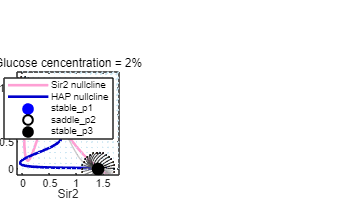


%trajectories
%point1 [0.0104 1.4094]

s4=0.0104;
h1=1.4094;
radius=0.3;
num_points_on_circle=30;
theta=linspace(0, 2*pi, num_points_on_circle + 1);
theta(end)=[];
S1=s4+radius*cos(theta);
H1=h1+radius*sin(theta);
initial_conditions=[S1',H1'];
colors = lines(size(initial_conditions, 1));
% 定义渐变的步数（即你希望渐变中有多少种颜色）
num_shades = 64; % 例如，64种不同的灰色
% 创建从0（黑色）到1（白色）的线性分布
% 对于灰色，R, G, B 分量是相同的
gray_values = linspace(0, 1, num_shades)'; % 注意这里的转置，使其成为列向量
% 将列向量复制三份，形成 RGB 矩阵
grayscale_colormap = [gray_values, gray_values, gray_values];
% 如果你想要从黑到“浅灰”，而不是到纯白，可以调整最大值
max_gray_value = 0.8; % 例如，到 R=G=B=0.8 的浅灰色
gray_values_to_light_gray = linspace(0, max_gray_value, num_shades)';
grayscale_colormap_light = [gray_values_to_light_gray, gray_values_to_light_gray, gray_values_to_light_gray];
% 从渐变色图中均匀取样，为每条轨迹分配一种颜色
% 确保取样索引在色图的有效范围内
indices = round(linspace(1, num_shades, size(initial_conditions,1)));
temp_colors = grayscale_colormap_light(indices, :);

tspan=[0 1000];
for i = 1:size(initial_conditions, 1)
    [t,sol]=ode45(@gly_ode, tspan, initial_conditions(i,:),[],glc(1));
    S_traj=sol(:,1);
    H_traj=sol(:,2);
    plot(S_traj, H_traj, 'Color', temp_colors(i,:),'LineWidth',1);
    plot(initial_conditions(i, 1), initial_conditions(i, 2), 'o', ...
        'MarkerSize', 1, 'MarkerFaceColor', colors(i, :), 'MarkerEdgeColor', 'k');
    hold on;
end
%point2 [0.4909 0.9359]
s2=0.4909;
h2=0.9359;
radius=0.3;
num_points_on_circle=30;
theta=linspace(0, 2*pi, num_points_on_circle + 1);
theta(end)=[];
S2=s2+radius*cos(theta);
H2=h2+radius*sin(theta);
initial_conditions=[S2',H2'];
tspan=[0 1000];
for i = 1:size(initial_conditions, 1)
    [t,sol]=ode45(@gly_ode, tspan, initial_conditions(i,:),[],glc(1));
    S_traj=sol(:,1);
    H_traj=sol(:,2);
    plot(S_traj, H_traj, 'Color', temp_colors(i,:),'LineWidth',1);
    plot(initial_conditions(i, 1), initial_conditions(i, 2), 'o', ...
        'MarkerSize', 1, 'MarkerFaceColor', colors(i, :), 'MarkerEdgeColor', 'k');
    hold on;
end
%point3 [1.4168 0.0109]
s3=1.4168;
h3=0.0109;
radius=0.3;
num_points_on_circle=30;
theta=linspace(0, 2*pi, num_points_on_circle + 1);
theta(end)=[];
S3=s3+radius*cos(theta);
H3=h3+radius*sin(theta);
initial_conditions=[S3',H3'];
tspan=[0 1000];
for i = 1:size(initial_conditions, 1)
    [t,sol]=ode45(@gly_ode, tspan, initial_conditions(i,:),[],glc(1));
    S_traj=sol(:,1);
    H_traj=sol(:,2);
    plot(S_traj, H_traj, 'Color', temp_colors(i,:),'LineWidth',0.8);
    plot(initial_conditions(i, 1), initial_conditions(i, 2), 'o', ...
        'MarkerSize', 1, 'MarkerFaceColor', colors(i, :), 'MarkerEdgeColor', 'k');
    hold on;
end

%plot equilibrium points
x1=x_eq1(1);y1=x_eq1(2);x2=x_eq2(1);y2=x_eq2(2);x3=x_eq3(1);y3=x_eq3(2);

% Equilibrium point 1: Stable
h_p1 = plot(x1, y1, 'o', 'MarkerSize', 8, 'MarkerEdgeColor', 'b', 'LineWidth', 1.5, 'MarkerFaceColor', 'b', 'DisplayName','stable_p1');

% Equilibrium point 2: Saddle (Unstable)
h_p2 = plot(x2, y2, 'o', 'MarkerSize', 8, 'MarkerEdgeColor', 'k', 'LineWidth', 1.5, 'MarkerFaceColor', 'none', 'DisplayName','saddle_p2');

% Equilibrium point 3: Stable
h_p3 = plot(x3, y3, 'o', 'MarkerSize', 8, 'MarkerEdgeColor', 'k', 'LineWidth', 1.5, 'MarkerFaceColor', 'k', 'DisplayName','stable_p3');

% Add legend
legend_entries = [h_1, h_2, h_p1, h_p2, h_p3];
legend_labels = {'Sir2 nullcline', 'HAP nullcline', 'stable_p1', 'saddle_p2', 'stable_p3'};
legend(legend_entries, legend_labels, 'Location', 'northeast');
lgd = legend(legend_entries, legend_labels, 'Location', 'northeast');
lgd.Interpreter = 'none'; % 确保文本作为纯字符串显示，而不是 TeX 语法
hold off;

%when total glucose level = 0.1%
[St,Ht]=piecewise_glucose(glc(2));

%nuclines
S3=0:0.01:2;
H3=(beta1+(S3.^3)./(Ks^3+S3.^3)).*(St-S3)./(gamma1.*S3)-ds/gamma1;

ax2 = subplot(1, 3, 2);
left_B = left_margin + subplot_width + subplot_gap;
ax2.Position = [left_B bottom_margin subplot_width subplot_height];
h_3=plot(S3,H3,'Color', [0.996, 0.627, 0.831], 'LineWidth', 2, 'DisplayName','Sir2 nullcline');
hold on;
H3=0:0.01:2;
S3=(beta2+(H3.^3)./(Kh^3+H3.^3)).*(Ht-H3)./(gamma2.*H3)-dh/gamma2;
h_4=plot(S3,H3,'Color', [0.0, 0.0, 0.8], 'LineWidth', 2, 'DisplayName','HAP nullcline');

%vector field
[S,H] = meshgrid(0:.1:2);
Xq = (beta1+(S.^3)./(Ks^3+S.^3)).*(St-S)-(ds+gamma1.*H).*S;
Yq = (beta2+(H.^3)./(Kh^3+H.^3)).*(Ht-H)-(ds+gamma2.*S).*H;
quiver(S,H, Xq, Yq, 'Color', [0.8, 0.9, 0.95], 'LineWidth', 1.2, 'AutoScaleFactor', 0.8, 'DisplayName','vector field');
title('Glucose cencentration = 0.1%')
xlim([-0.1 1.8]);
ylim([-0.1 1.8]);
xlabel('Sir2');
ylabel('HAP');
%trajectories

%Find the equilibria
%point4 [0.01,1.51]
[St,Ht]=piecewise_glucose(glc(2));
[x_eq4, J4] = newton_gly(@gly_ode,[0.01,1.51]',[St,Ht],glc(2));
disp('Equilibrium point 4:');

Equilibrium point 4:


disp(x_eq4);

    0.0100
    1.5063



disp('Jacobian matrix 4:');

Jacobian matrix 4:


disp(J4);

   -1.6129   -0.0100
   -1.5063   -1.1949



residual = gly_ode(0,x_eq4,glc(2));
disp('residual norm 4:');

residual norm 4:


disp(norm(residual));

   2.5091e-06



[W4,D4]=eig(J4);
L4=diag(D4);
eigen_value1=L4(1);
eigen_value2=L4(2);
eigen_vector1=W4(:,1);
eigen_vector2=W4(:,2);
if real(eigen_value1)>0 && real(eigen_value2)>0
    disp('The eigenvalues of Jacobian matrix 4 are:')
    disp(L4);
    disp('Equilibrium point 4 is an unstable focus');
elseif real(eigen_value1)<0 && real(eigen_value2)<0
    disp('The eigenvalues of Jacobian matrix 4 are:')
    disp(L4);
    disp('Equilibrium point 4 is a stable focus');
else
    disp('The eigenvalues of Jacobian matrix 4 are:')
    disp(L4);
    disp('Equilibrium point 4 is a saddle');
end

The eigenvalues of Jacobian matrix 4 are:


   -1.6463
   -1.1614



Equilibrium point 4 is a stable focus


%point5 [0.55,0.0.97]
[x_eq5, J5] = newton_gly(@gly_ode,[0.55,0.97]',[St,Ht],glc(2));
disp('Equilibrium point 5:');

Equilibrium point 5:


disp(x_eq5);

    0.5478
    0.9745



disp('Jacobian matrix 5:');

Jacobian matrix 5:


disp(J5);

   -0.1644   -0.5478
   -0.9745   -1.1387



residual = gly_ode(0,x_eq5,glc(2));
disp('residual norm 5:');

residual norm 5:


disp(norm(residual));

   1.6324e-05



[W5,D5]=eig(J5);
L5=diag(D5);
eigen_value1=L5(1);
eigen_value2=L5(2);
eigen_vector1=W5(:,1);
eigen_vector2=W5(:,2);
if real(eigen_value1)>0 && real(eigen_value2)>0
    disp('The eigenvalues of Jacobian matrix 5 are:')
    disp(L5);
    disp('Equilibrium point 5 is an unstable focus');
elseif real(eigen_value1)<0 && real(eigen_value2)<0
    disp('The eigenvalues of Jacobian matrix 5 are:')
    disp(L5);
    disp('Equilibrium point 5 is a stable focus');
else
    disp('The eigenvalues of Jacobian matrix 5 are:')
    disp(L5);
    disp('Equilibrium point 5 is a saddle');
end

The eigenvalues of Jacobian matrix 5 are:


    0.2266
   -1.5297



Equilibrium point 5 is a saddle


%point6 [0.723,0.816]
[x_eq6, J6] = newton_gly(@gly_ode,[0.723,0.816]',[St,Ht],glc(2));
disp('Equilibrium point 6:');

Equilibrium point 6:


disp(x_eq6);

    0.7233
    0.8163



disp('Jacobian matrix 6:');

Jacobian matrix 6:


disp(J6);

   -0.9207   -0.7233
   -0.8163   -0.8067



residual = gly_ode(0,x_eq6,glc(2));
disp('residual norm 6:');

residual norm 6:


disp(norm(residual));

   3.7941e-07



[W6,D6]=eig(J6);
L6=diag(D6);
eigen_value1=L6(1);
eigen_value2=L6(2);
eigen_vector1=W6(:,1);
eigen_vector2=W6(:,2);
if real(eigen_value1)>0 && real(eigen_value2)>0
    disp('The eigenvalues of Jacobian matrix 6 are:')
    disp(L6);
    disp('Equilibrium point 6 is an unstable focus');
elseif real(eigen_value1)<0 && real(eigen_value2)<0
    disp('The eigenvalues of Jacobian matrix 6 are:')
    disp(L6);
    disp('Equilibrium point 6 is a stable focus');
else
    disp('The eigenvalues of Jacobian matrix 6 are:')
    disp(L6);
    disp('Equilibrium point 6 is a saddle');
end

The eigenvalues of Jacobian matrix 6 are:


   -1.6342
   -0.0932



Equilibrium point 6 is a stable focus


%point7 [0.82,0.69]
[x_eq7, J7] = newton_gly(@gly_ode,[0.82,0.69]',[St,Ht],glc(2));
disp('Equilibrium point 7:');

Equilibrium point 7:


disp(x_eq7);

    0.8227
    0.6835



disp('Jacobian matrix 7:');

Jacobian matrix 7:


disp(J7);

   -1.1238   -0.8227
   -0.6835   -0.2904



residual = gly_ode(0,x_eq7,glc(2));
disp('residual norm 7:');

residual norm 7:


disp(norm(residual));

   5.0086e-07



[W7,D7]=eig(J7);
L7=diag(D7);
eigen_value1=L7(1);
eigen_value2=L7(2);
eigen_vector1=W7(:,1);
eigen_vector2=W7(:,2);
if real(eigen_value1)>0 && real(eigen_value2)>0
    disp('The eigenvalues of Jacobian matrix 7 are:')
    disp(L7);
    disp('Equilibrium point 7 is an unstable focus');
elseif real(eigen_value1)<0 && real(eigen_value2)<0
    disp('The eigenvalues of Jacobian matrix 7 are:')
    disp(L7);
    disp('Equilibrium point 7 is a stable focus');
else
    disp('The eigenvalues of Jacobian matrix 7 are:')
    disp(L7);
    disp('Equilibrium point 7 is a saddle');
end

The eigenvalues of Jacobian matrix 7 are:


   -1.5650
    0.1507



Equilibrium point 7 is a saddle


%point8 [1.45,0.015]
[x_eq8, J8] = newton_gly(@gly_ode,[1.45,0.015]',[St,Ht],glc(2));
disp('Equilibrium point 8:');

Equilibrium point 8:


disp(x_eq8);

    1.4526
    0.0113



disp('Jacobian matrix 8:');

Jacobian matrix 8:


disp(J8);

   -1.0630   -1.4526
   -0.0113   -1.7594



residual = gly_ode(0,x_eq8,glc(2));
disp('residual norm 8:');

residual norm 8:


disp(norm(residual));

   1.6544e-05



[W8,D8]=eig(J8);
L8=diag(D8);
eigen_value1=L8(1);
eigen_value2=L8(2);
eigen_vector1=W8(:,1);
eigen_vector2=W8(:,2);
if real(eigen_value1)>0 && real(eigen_value2)>0
    disp('The eigenvalues of Jacobian matrix 8 are:')
    disp(L8);
    disp('Equilibrium point 8 is an unstable focus');
elseif real(eigen_value1)<0 && real(eigen_value2)<0
    disp('The eigenvalues of Jacobian matrix 8 are:')
    disp(L8);
    disp('Equilibrium point 8 is a stable focus');
else
    disp('The eigenvalues of Jacobian matrix 8 are:')
    disp(L8);
    disp('Equilibrium point 8 is a saddle');
end

The eigenvalues of Jacobian matrix 8 are:


   -1.0401
   -1.7823



Equilibrium point 8 is a stable focus


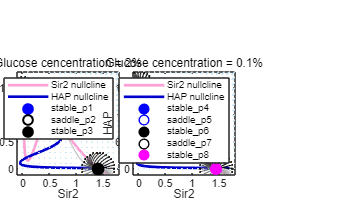


%trajectories
%point4 [0.0100 1.5063]
s4=0.0100;
h4=1.5063;
radius=0.3;
num_points_on_circle=30;
theta=linspace(0, 2*pi, num_points_on_circle + 1);
theta(end)=[];
S4=s4+radius*cos(theta);
H4=h4+radius*sin(theta);
initial_conditions=[S4',H4'];
tspan=[0 1000];
for i = 1:size(initial_conditions, 1)
    [t,sol]=ode45(@gly_ode, tspan, initial_conditions(i,:),[],glc(2));
    S_traj=sol(:,1);
    H_traj=sol(:,2);
    plot(S_traj, H_traj, 'Color', temp_colors(i,:),'LineWidth',1);
    plot(initial_conditions(i, 1), initial_conditions(i, 2), 'o', ...
        'MarkerSize', 1, 'MarkerFaceColor', colors(i, :), 'MarkerEdgeColor', 'k');
    hold on;
end
%point5 [0.5478 0.9745]
s5=0.5478;
h5=0.9745;
radius=0.2;
num_points_on_circle=30;
theta=linspace(0, 2*pi, num_points_on_circle + 1);
theta(end)=[];
S5=s5+radius*cos(theta);
H5=h5+radius*sin(theta);
initial_conditions=[S5',H5'];
tspan=[0 1000];
for i = 1:size(initial_conditions, 1)
    [t,sol]=ode45(@gly_ode, tspan, initial_conditions(i,:),[],glc(2));
    S_traj=sol(:,1);
    H_traj=sol(:,2);
    plot(S_traj, H_traj, 'Color', temp_colors(i,:),'LineWidth',1);
    plot(initial_conditions(i, 1), initial_conditions(i, 2), 'o', ...
        'MarkerSize', 1, 'MarkerFaceColor', colors(i, :), 'MarkerEdgeColor', 'k');
    hold on;
end
%point6 [0.7233 0.8163]
s6=0.7233;
h6=0.8163;
radius=0.2;
num_points_on_circle=30;
theta=linspace(0, 2*pi, num_points_on_circle + 1);
theta(end)=[];
S6=s6+radius*cos(theta);
H6=h6+radius*sin(theta);
initial_conditions=[S6',H6'];
tspan=[0 1000];
for i = 1:size(initial_conditions, 1)
    [t,sol]=ode45(@gly_ode, tspan, initial_conditions(i,:),[],glc(2));
    S_traj=sol(:,1);
    H_traj=sol(:,2);
    plot(S_traj, H_traj, 'Color', temp_colors(i,:),'LineWidth',1);
    plot(initial_conditions(i, 1), initial_conditions(i, 2), 'o', ...
        'MarkerSize', 1, 'MarkerFaceColor', colors(i, :), 'MarkerEdgeColor', 'k');
    hold on;
end
%point7 [0.8227 0.6835]
s7=0.8227;
h7=0.6835;
radius=0.2;
num_points_on_circle=30;
theta=linspace(0, 2*pi, num_points_on_circle + 1);
theta(end)=[];
S7=s7+radius*cos(theta);
H7=h7+radius*sin(theta);
initial_conditions=[S7',H7'];
tspan=[0 1000];
for i = 1:size(initial_conditions, 1)
    [t,sol]=ode45(@gly_ode, tspan, initial_conditions(i,:),[],glc(2));
    S_traj=sol(:,1);
    H_traj=sol(:,2);
    plot(S_traj, H_traj, 'Color', temp_colors(i,:),'LineWidth',1);
    plot(initial_conditions(i, 1), initial_conditions(i, 2), 'o', ...
        'MarkerSize', 1, 'MarkerFaceColor', colors(i, :), 'MarkerEdgeColor', 'k');
    hold on;
end
%point8 [1.4526 0.0113]
s8=1.4526;
h8=0.0113;
radius=0.3;
num_points_on_circle=30;
theta=linspace(0, 2*pi, num_points_on_circle + 1);
theta(end)=[];
S8=s8+radius*cos(theta);
H8=h8+radius*sin(theta);
initial_conditions=[S8',H8'];
tspan=[0 1000];
for i = 1:size(initial_conditions, 1)
    [t,sol]=ode45(@gly_ode, tspan, initial_conditions(i,:),[],glc(2));
    S_traj=sol(:,1);
    H_traj=sol(:,2);
    plot(S_traj, H_traj, 'Color', temp_colors(i,:),'LineWidth',0.8);
    plot(initial_conditions(i, 1), initial_conditions(i, 2), 'o', ...
        'MarkerSize', 1, 'MarkerFaceColor', colors(i, :), 'MarkerEdgeColor', 'k');
end

%plot equilibrium points
x4=x_eq4(1);y4=x_eq4(2);x5=x_eq5(1);y5=x_eq5(2);x6=x_eq6(1);y6=x_eq6(2);x7=x_eq7(1);y7=x_eq7(2);x8=x_eq8(1);y8=x_eq8(2);
h_p4 = plot(x4, y4, 'o', 'MarkerSize', 8, 'MarkerEdgeColor', 'b', 'LineWidth', 1, 'MarkerFaceColor', 'b', 'DisplayName','point 1');
h_p5 = plot(x5, y5, 'o', 'MarkerSize', 8, 'MarkerEdgeColor', 'b', 'LineWidth', 1, 'MarkerFaceColor', 'none','DisplayName','point 2');
h_p6 = plot(x6, y6, 'o', 'MarkerSize', 8, 'MarkerEdgeColor', 'k', 'LineWidth', 1, 'MarkerFaceColor', 'k','DisplayName','point 3');
h_p7 = plot(x7, y7, 'o', 'MarkerSize', 8, 'MarkerEdgeColor', 'k', 'LineWidth', 1, 'MarkerFaceColor', 'none','DisplayName','point 4');
h_p8 = plot(x8, y8, 'o', 'MarkerSize', 8, 'MarkerEdgeColor', 'm', 'LineWidth', 1, 'MarkerFaceColor', 'm','DisplayName','point 5');
% Add legend
legend_entries = [h_3, h_4, h_p4, h_p5, h_p6, h_p7, h_p8];
legend_labels = {'Sir2 nullcline', 'HAP nullcline', 'stable_p4', 'saddle_p5', 'stable_p6', 'saddle_p7', 'stable_p8'};
legend(legend_entries, legend_labels, 'Location', 'northeast');
lgd = legend(legend_entries, legend_labels, 'Location', 'northeast');
lgd.Interpreter = 'none'; % 确保文本作为纯字符串显示，而不是 TeX 语法
hold off;

%when total glucose level = 0.02%
[St,Ht]=piecewise_glucose(glc(3));
%nuclines
S8=0:0.01:2;
H8=(beta1+(S8.^3)./(Ks^3+S8.^3)).*(St-S8)./(gamma1.*S8)-ds/gamma1;

ax3 = subplot(1, 3, 3);
left_C = left_B + subplot_width + subplot_gap;
ax3.Position = [left_C bottom_margin subplot_width subplot_height];
h_5=plot(S8,H8,'Color', [0.996, 0.627, 0.831],'LineWidth',2, 'DisplayName','Sir2 nullcline');
hold on;
H8=0:0.01:2;
S8=(beta2+(H8.^3)./(Kh^3+H8.^3)).*(Ht-H8)./(gamma2.*H8)-dh/gamma2;
h_6=plot(S8,H8,'Color', [0.0, 0.0, 0.8],'LineWidth',2, 'DisplayName','HAP nullcline');
%vector field
[S,H] = meshgrid(0:.1:2);
Xq = (beta1+(S.^3)./(Ks^3+S.^3)).*(St-S)-(ds+gamma1.*H).*S;
Yq = (beta2+(H.^3)./(Kh^3+H.^3)).*(Ht-H)-(ds+gamma2.*S).*H;
quiver(S,H, Xq, Yq, 'Color', [0.8, 0.9, 0.95], 'LineWidth', 1.2, 'AutoScaleFactor', 0.8, 'DisplayName','vector field');
title('Glucose cencentration = 0.02%')
xlim([-0.1 1.8]);
ylim([-0.1 1.8]);
xlabel('Sir2');
ylabel('HAP');
%trajectories

%Find the equilibria
%point9 [0.01,1.57]
[St,Ht]=piecewise_glucose(glc(3));
[x_eq9, J9] = newton_gly(@gly_ode,[0.01,1.57]',[St,Ht],glc(3));
disp('Equilibrium point 9:');

Equilibrium point 9:


disp(x_eq9);

    0.0098
    1.5929



disp('Jacobian matrix 9:');

Jacobian matrix 9:


disp(J9);

   -1.6995   -0.0098
   -1.5929   -1.2129



residual = gly_ode(0,x_eq9,glc(3));
disp('residual norm 9:');

residual norm 9:


disp(norm(residual));

   8.1284e-05



[W9,D9]=eig(J9);
L9=diag(D9);
eigen_value1=L9(1);
eigen_value2=L9(2);
eigen_vector1=W9(:,1);
eigen_vector2=W9(:,2);
if real(eigen_value1)>0 && real(eigen_value2)>0
    disp('The eigenvalues of Jacobian matrix 9 are:')
    disp(L9);
    disp('Equilibrium point 9 is an unstable focus');
elseif real(eigen_value1)<0 && real(eigen_value2)<0
    disp('The eigenvalues of Jacobian matrix 9 are:')
    disp(L9);
    disp('Equilibrium point 9 is a stable focus');
else
    disp('The eigenvalues of Jacobian matrix 9 are:')
    disp(L9);
    disp('Equilibrium point 9 is a saddle');
end

The eigenvalues of Jacobian matrix 9 are:


   -1.7296
   -1.1828



Equilibrium point 9 is a stable focus


%point10 [0.92,0.59]
[x_eq10, J10] = newton_gly(@gly_ode,[0.92,0.59]',[St,Ht],glc(3));
disp('Equilibrium point 10:');

Equilibrium point 10:


disp(x_eq10);

    0.9186
    0.5913



disp('Jacobian matrix 10:');

Jacobian matrix 10:


disp(J10);

   -1.2330   -0.9186
   -0.5913    0.2233



residual = gly_ode(0,x_eq10,glc(3));
disp('residual norm 10:');

residual norm 10:


disp(norm(residual));

   2.3745e-06



[W10,D10]=eig(J8);
L10=diag(D10);
eigen_value1=L10(1);
eigen_value2=L10(2);
eigen_vector1=W10(:,1);
eigen_vector2=W10(:,2);
if real(eigen_value1)>0 && real(eigen_value2)>0
    disp('The eigenvalues of Jacobian matrix 10 are:')
    disp(L10);
    disp('Equilibrium point 10 is an unstable focus');
elseif real(eigen_value1)<0 && real(eigen_value2)<0
    disp('The eigenvalues of Jacobian matrix 10 are:')
    disp(L10);
    disp('Equilibrium point 10 is a stable focus');
else
    disp('The eigenvalues of Jacobian matrix 10 are:')
    disp(L10);
    disp('Equilibrium point 10 is a saddle');
end

The eigenvalues of Jacobian matrix 10 are:


   -1.0401
   -1.7823



Equilibrium point 10 is a stable focus


%point11 [1.47,0.02]
[x_eq11, J11] = newton_gly(@gly_ode,[1.47,0.02]',[St,Ht],glc(3));
disp('Equilibrium point 11:');

Equilibrium point 11:


disp(x_eq11);

    1.4884
    0.0117



disp('Jacobian matrix 11:');

Jacobian matrix 11:


disp(J11);

   -1.0673   -1.4884
   -0.0117   -1.7948



residual = gly_ode(0,x_eq11,glc(3));
disp('residual norm 11:');

residual norm 11:


disp(norm(residual));

   7.3653e-09



[W11,D11]=eig(J8);
L11=diag(D11);
eigen_value1=L11(1);
eigen_value2=L11(2);
eigen_vector1=W11(:,1);
eigen_vector2=W11(:,2);
if real(eigen_value1)>0 && real(eigen_value2)>0
    disp('The eigenvalues of Jacobian matrix 11 are:')
    disp(L11);
    disp('Equilibrium point 11 is an unstable focus');
elseif real(eigen_value1)<0 && real(eigen_value2)<0
    disp('The eigenvalues of Jacobian matrix 11 are:')
    disp(L11);
    disp('Equilibrium point 11 is a stable focus');
else
    disp('The eigenvalues of Jacobian matrix 11 are:')
    disp(L11);
    disp('Equilibrium point 11 is a saddle');
end

The eigenvalues of Jacobian matrix 11 are:


   -1.0401
   -1.7823



Equilibrium point 11 is a stable focus


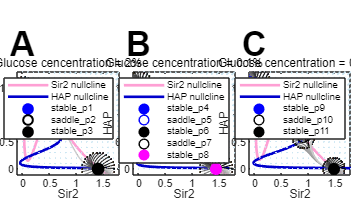


%trajectories
%point9 [0.0098 1.5929]
s9=0.0098;
h9=1.5929;
radius=0.3;
num_points_on_circle=30;
theta=linspace(0, 2*pi, num_points_on_circle + 1);
theta(end)=[];
S9=s9+radius*cos(theta);
H9=h9+radius*sin(theta);
initial_conditions=[S9',H9'];
tspan=[0 1000];
for i = 1:size(initial_conditions, 1)
    [t,sol]=ode45(@gly_ode, tspan, initial_conditions(i,:),[],glc(3));
    S_traj=sol(:,1);
    H_traj=sol(:,2);
    plot(S_traj, H_traj, 'Color', temp_colors(i,:),'LineWidth',1);
    plot(initial_conditions(i, 1), initial_conditions(i, 2), 'o', ...
        'MarkerSize', 1, 'MarkerFaceColor', colors(i, :), 'MarkerEdgeColor', 'k');
    hold on;
end
%point10  [0.9186 0.5913]
s10=0.9186;
h10=0.5913;
radius=0.2;
num_points_on_circle=30;
theta=linspace(0, 2*pi, num_points_on_circle + 1);
theta(end)=[];
S10=s10+radius*cos(theta);
H10=h10+radius*sin(theta);
initial_conditions=[S10',H10'];
tspan=[0 1000];
for i = 1:size(initial_conditions, 1)
    [t,sol]=ode45(@gly_ode, tspan, initial_conditions(i,:),[],glc(3));
    S_traj=sol(:,1);
    H_traj=sol(:,2);
    plot(S_traj, H_traj, 'Color', temp_colors(i,:),'LineWidth',1);
    plot(initial_conditions(i, 1), initial_conditions(i, 2), 'o', ...
        'MarkerSize', 1, 'MarkerFaceColor', colors(i, :), 'MarkerEdgeColor', 'k');
    hold on;
end
%point11 [1.4884 0.0117]
s11=1.4884;
h11=0.0117;
radius=0.2;
num_points_on_circle=30;
theta=linspace(0, 2*pi, num_points_on_circle + 1);
theta(end)=[];
S11=s11+radius*cos(theta);
H11=h11+radius*sin(theta);
initial_conditions=[S11',H11'];
tspan=[0 1000];
for i = 1:size(initial_conditions, 1)
    [t,sol]=ode45(@gly_ode, tspan, initial_conditions(i,:),[],glc(3));
    S_traj=sol(:,1);
    H_traj=sol(:,2);
    plot(S_traj, H_traj, 'Color', temp_colors(i,:),'LineWidth',0.8);
    plot(initial_conditions(i, 1), initial_conditions(i, 2), 'o', ...
        'MarkerSize', 1, 'MarkerFaceColor', colors(i, :), 'MarkerEdgeColor', 'k');
    hold on;
end

%plot equilibrium points
x1=x_eq9(1);y1=x_eq9(2);x2=x_eq10(1);y2=x_eq10(2);x3=x_eq11(1);y3=x_eq11(2);
h_p9 = plot(x1, y1, 'o', 'MarkerSize', 8, 'MarkerEdgeColor', 'b', 'LineWidth', 1, 'MarkerFaceColor', 'b', 'DisplayName','point 1');
h_p10 = plot(x2, y2, 'o', 'MarkerSize', 8, 'MarkerEdgeColor', 'k', 'LineWidth', 1, 'MarkerFaceColor', 'none','DisplayName','point 2');
h_p11 = plot(x3, y3, 'o', 'MarkerSize', 8, 'MarkerEdgeColor', 'k', 'LineWidth', 1, 'MarkerFaceColor', 'k','DisplayName','point 3');
% Add legend
legend_entries = [h_5, h_6, h_p9, h_p10, h_p11];
legend_labels = {'Sir2 nullcline', 'HAP nullcline', 'stable_p9', 'saddle_p10', 'stable_p11'};
legend(legend_entries, legend_labels, 'Location', 'northeast');
lgd = legend(legend_entries, legend_labels, 'Location', 'northeast');
lgd.Interpreter = 'none'; % 确保文本作为纯字符串显示，而不是 TeX 语法
hold off;
% 设定标签的公共 Y 坐标（在子图的顶部略上方）
label_y_pos = bottom_margin + subplot_height + 0.005; % 比子图顶部高

% 设定字体大小和粗细
label_fontSize = 25; % 根据需要调整
label_fontWeight = 'bold';
label_color = 'k';

% 添加 A
annotation(gcf, 'textbox', [0.01, label_y_pos, 0.05, 0.05], ... % X 坐标稍微向左偏移一点
           'String', 'A', ...
           'FontSize', label_fontSize, ...
           'FontWeight', label_fontWeight, ...
           'Color', label_color, ...
           'LineStyle', 'none', ... % 无边框
           'HorizontalAlignment', 'left', ...
           'VerticalAlignment', 'bottom'); % 文本框底部与 Y 坐标对齐

% 添加 B
annotation(gcf, 'textbox', [0.01 + subplot_width + subplot_gap, label_y_pos, 0.05, 0.05], ...
           'String', 'B', ...
           'FontSize', label_fontSize, ...
           'FontWeight', label_fontWeight, ...
           'Color', label_color, ...
           'LineStyle', 'none', ...
           'HorizontalAlignment', 'left', ...
           'VerticalAlignment', 'bottom');

% 添加 C
annotation(gcf, 'textbox', [0.01 + (subplot_width + subplot_gap)*2, label_y_pos, 0.05, 0.05], ...
           'String', 'C', ...
           'FontSize', label_fontSize, ...
           'FontWeight', label_fontWeight, ...
           'Color', label_color, ...
           'LineStyle', 'none', ...
           'HorizontalAlignment', 'left', ...
           'VerticalAlignment', 'bottom');
exportgraphics(gcf, 'phase_plane_glc_tot.pdf', 'ContentType', 'vector'); 